**Question 2:**

First, I load the data and use 2-fold cross validation to split it to train and test sets as below:

myStruct = load('problem2.mat'); 
x_initial = myStruct.x;
y_initial = myStruct.y;

indices = randperm(length(myStruct.x));
x_shuffled = x_initial(indices,:);
y_shuffled = y_initial(indices,:);

num_samples = length(myStruct.x);
half_num_samples = floor(num_samples / 2);

x = x_shuffled(1:half_num_samples, :); 
y = y_shuffled(1:half_num_samples, :);
xT = x_shuffled(half_num_samples+1:end, :);
yT = y_shuffled(half_num_samples+1:end, :);

Next, I use a function like in question 1, to train the model and calculate the losses for different values of Lambda:

lambda 1: Training Error = 22.443468
lambda 1000: Testing Error = 63.375102


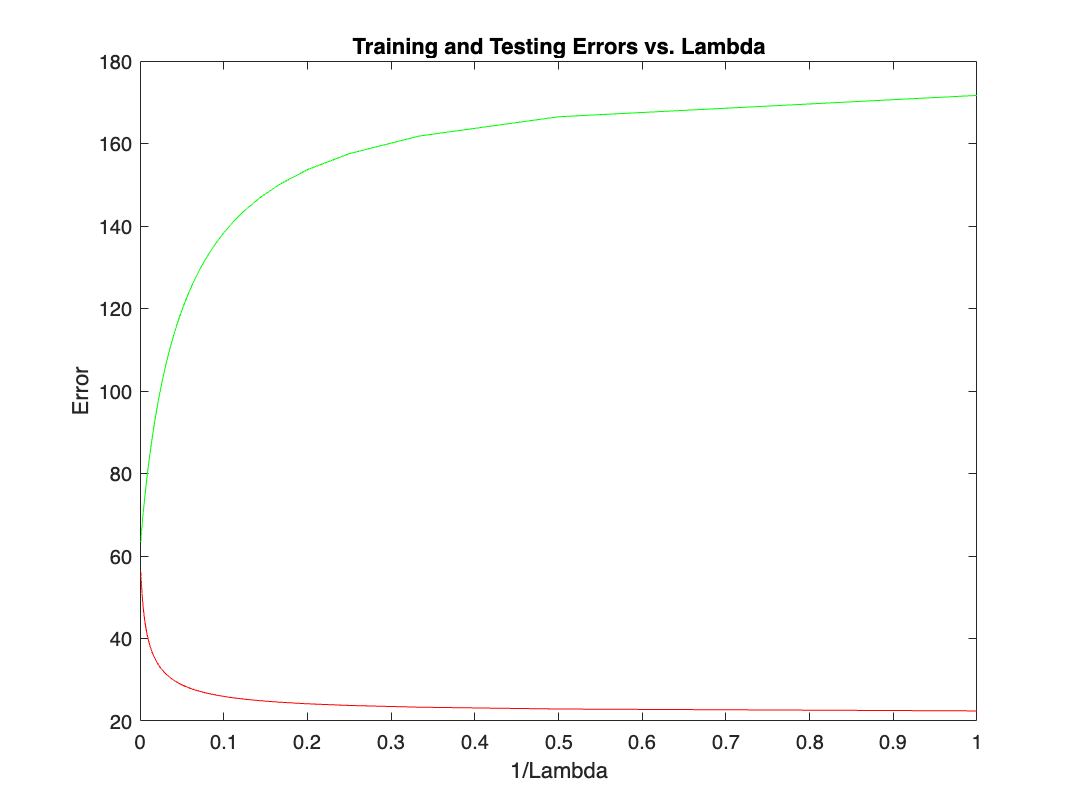

[err_1, model_1, errT_1] = linearreg_1(x, y, xT, yT);

The second function, uses gradient decent to find the values of Theta.  Next, I define the number of iterations and learning rate for implementing the gradient descent algorithm in the training process.

lambda 1: Training Error = 22.443568
lambda 1000: Testing Error = 63.375102


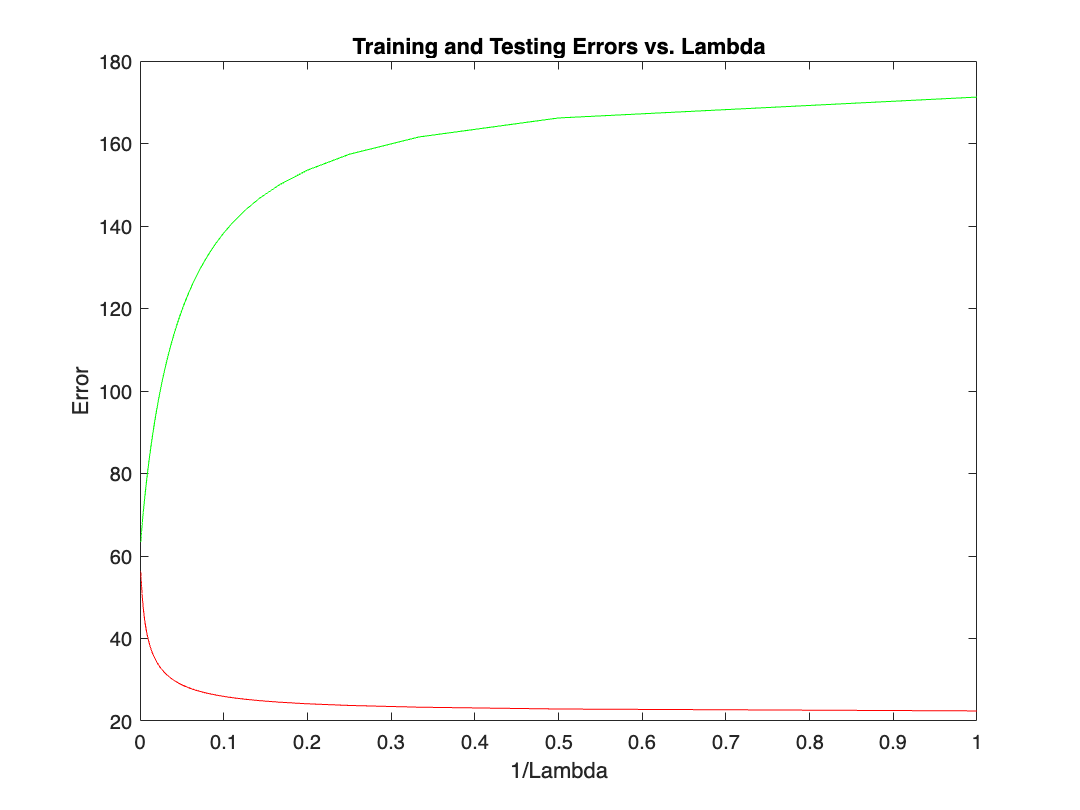

num_iterations = 5000; 
learning_rate = 0.01;
[err_2, model_2, errT_2] = linearreg(x, y, xT, yT, num_iterations, learning_rate);

The first function is defined as below. After iterating for different values of Lambda, we calculate the train and test loss for each, and plot the risk regarding to Lambda.

The second function has the same goal, it only uses gradient decent to find the values of Theta.

After visualizing the models, we see that we get the same results. The train error decreases and the test error increases as the value of Lambda decreases.

function [err_1, model_1, errT_1] = linearreg_1(x, y, xT, yT)

lambda_range = 1:1000;

train_risk = zeros(length(lambda_range), 1);
test_risk = zeros(length(lambda_range), 1);


for lambda_idx = 1:length(lambda_range)
    lambda = lambda_range(lambda_idx);
    
    model_1 = inv(x'*x + lambda*eye(100))* x' * y;
    err_1 = (1 / (2 * length(x))) * sum((y - x * model_1).^2) + (lambda / (2 * length(x))) * sum(model_1.^2);
    errT_1 = (1 / (2 * length(xT))) * sum((yT - xT * model_1).^2) + (lambda / (2 * length(xT))) * sum(model_1.^2);
    train_risk(lambda) = err_1;
    test_risk(lambda) = errT_1;

end
    best_train_idx = find(train_risk == min(train_risk));    
    best_test_idx = find(test_risk == min(test_risk));

    fprintf('lambda %d: Training Error = %f\n', best_train_idx, min(train_risk));
    fprintf('lambda %d: Testing Error = %f\n', best_test_idx, min(test_risk));

figure;
plot(1 ./ lambda_range, train_risk, 'r',  'DisplayName', 'Training Error');
hold on;
plot(1 ./ lambda_range, test_risk, 'g',  'DisplayName', 'Testing Error');
title('Training and Testing Errors vs. Lambda');
xlabel('1/Lambda');
ylabel('Error');
hold off;

end



function [err_2, model_2, errT_2] = linearreg(x, y, xT, yT, num_iterations, learning_rate)

lambda_range = 1:1000;

train_risk = zeros(length(lambda_range), 1);
test_risk = zeros(length(lambda_range), 1);

for lambda = 1:1000

    model_2 = zeros(size(x, 2), 1);

    for iter = 1:num_iterations
        predictions = x * model_2;
        gradient = (-1/length(x)) * (x' * (y - predictions)) + (lambda/length(x)) * model_2;
        model_2 = model_2 - (learning_rate * gradient);
        err_2 = (1 / (2 * length(x))) * sum((y - predictions).^2) + ((lambda / (2 * length(x))) * sum(model_2.^2));
        
        if (nargin == 6)
            predictionsT = xT * model_2;
            errT_2 = (1 / (2 * length(xT))) * sum((yT - predictionsT).^2) + (lambda / (2 * length(xT))) * sum(model_2.^2);
        end
        
    end

    train_risk(lambda) = err_2;
    test_risk(lambda) = errT_2;

end
    best_train_idx = find(train_risk == min(train_risk));    
    best_test_idx = find(test_risk == min(test_risk));

    fprintf('lambda %d: Training Error = %f\n', best_train_idx, min(train_risk));
    fprintf('lambda %d: Testing Error = %f\n', best_test_idx, min(test_risk));

figure;
plot(1 ./ lambda_range, train_risk, 'r', 'DisplayName', 'Training Error');
hold on;
plot(1 ./ lambda_range, test_risk, 'g', 'DisplayName', 'Testing Error');
title('Training and Testing Errors vs. Lambda');
xlabel('1/Lambda');
ylabel('Error');
hold off;


end